# Equlibrium analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
%Prefix = '2020-11-21-optoknirps_eve4_6_embryo5'; APflip = 1;
%Prefix = '2020-11-22-optoknirps_eve4_6_embryo6'; APflip = 0;
%Prefix = '2020-11-24-optoknirps_eve4_6_embryo7'; APflip = 0;
Prefix = '2020-11-27-optoknirps_eve4_6_embryo8'; APflip = 1;


Initialize some parameters

analysisInit = 0;
analysisFinal = 38;

avrInit = 20;
avrFinal = 25;

timeFinal = 0:1/3:45;

% initialize binning parameters
binNum = 26;
edges = linspace(-0.2,0.2,binNum);

% eYFP background (estimated from data)
%eYFP_background = 1.5E5;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/' Prefix];

% Make result path
ResultPath = ['./result/' Prefix];

mkdir(FigPath)

mkdir(ResultPath)

% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to CompiledParticles
LoadParticlePath = [DynamicsResultsFolder '/' Prefix '/CompiledParticles.mat']; 
LoadNucleiPath = [DynamicsResultsFolder '/' Prefix '/' Prefix '_lin.mat'];
LoadComNucleiPath = [DynamicsResultsFolder '/' Prefix '/CompiledNuclei.mat']; 

data.particle = load(LoadParticlePath);
data.nuclei = load(LoadComNucleiPath);
data.sch = load(LoadNucleiPath);

ElapsedTime = data.particle.ElapsedTime-data.particle.ElapsedTime(data.nuclei.nc14);

% find frames to analyze
initFrame = find(ElapsedTime<=analysisInit,1,'last');
finalFrame = find(ElapsedTime>analysisFinal,1);

% total number of frames
totalFrame = finalFrame-initFrame + 1;

% find frames to average
avrInitFrame = find(ElapsedTime<=avrInit,1,'last');
avrFinalFrame = find(ElapsedTime>avrFinal,1);

totalTime = ElapsedTime(initFrame:finalFrame);

## Part 2: Quality check on nuclei tracking

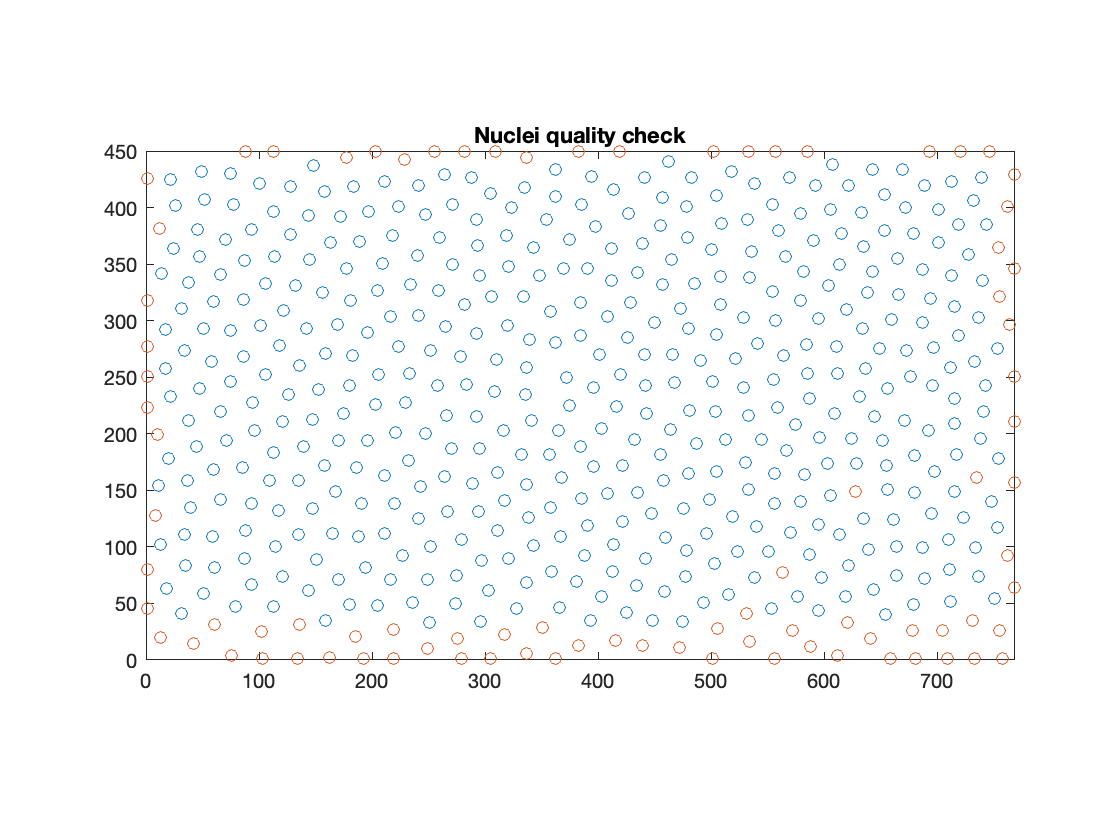

% Quality check and save the nuclei that passed the test
% Requires the nuclei to have continuous trace until lateral movement
X_pass = [];
Y_pass = [];

X_fail = [];
Y_fail = [];

schPass = [];

schnitzcells = data.sch.schnitzcells;

for i = 1:size(schnitzcells,2)
    index_s = find(schnitzcells(i).frames == initFrame);
    index_f = find(schnitzcells(i).frames == finalFrame);
    fluo_temp = max(schnitzcells(i).Fluo(index_s:index_f,:),[],2);
    result = sum(isnan(fluo_temp));
    % quality check
    if ~isempty(index_s) && ~isempty(index_f) && (index_f-index_s == finalFrame-initFrame)  ...
            && (result == 0)
        schPass = [schPass, i];
        X_pass = [X_pass, schnitzcells(i).cenx(index_s)];
        Y_pass = [Y_pass, schnitzcells(i).ceny(index_s)];
    else
        X_fail = [X_fail, schnitzcells(i).cenx(index_s)];
        Y_fail = [Y_fail, schnitzcells(i).ceny(index_s)];
    end
end

fig = figure(1);
plot(X_pass,Y_pass,'o')
hold on
plot(X_fail,Y_fail,'o')
hold off
axis equal
xlim([0 768])
ylim([0 450])
title('Nuclei quality check')

## Part 3: Compile the schnitzcells together

compile based on each frame

nucleiNum = length(schPass);

% Initialize storage
processed_data(1).xcoord = [];
processed_data(1).ycoord = [];

processed_data(1).schnitznum = [];
processed_data(1).NuclearFluo = [];
processed_data(1).SpotFluo = [];


% Compile all the nuclei in each frame and assign basic info
for i = 1:nucleiNum
    schTemp = schPass(i);
    index_s = find(schnitzcells(schTemp).frames == initFrame);
    index_f = find(schnitzcells(schTemp).frames == finalFrame);
    
    for j = index_s:index_f
        frameTemp = schnitzcells(schTemp).frames(j);
        x_coord = schnitzcells(schTemp).cenx(j);
        y_coord = schnitzcells(schTemp).ceny(j);
        fluo = max(schnitzcells(schTemp).Fluo(j,:));
        try
            processed_data(frameTemp).xcoord = [processed_data(frameTemp).xcoord, x_coord];
            processed_data(frameTemp).ycoord = [processed_data(frameTemp).ycoord, y_coord];
            processed_data(frameTemp).schnitznum = [processed_data(frameTemp).schnitznum, schTemp];
            processed_data(frameTemp).SpotFluo = [processed_data(frameTemp).SpotFluo, 0];
            processed_data(frameTemp).NuclearFluo = [processed_data(frameTemp).NuclearFluo fluo];  
        catch
            processed_data(frameTemp).xcoord = x_coord;
            processed_data(frameTemp).ycoord = y_coord;
            processed_data(frameTemp).schnitznum = schTemp;
            processed_data(frameTemp).SpotFluo = 0;
            processed_data(frameTemp).NuclearFluo = fluo;
        end
    end
end

CompiledParticles = data.particle.CompiledParticles;

% Assign particle info to all the nuclei
for i = 1:size(CompiledParticles{1,1},2)
    schnitz_num = CompiledParticles{1,1}(i).schnitz;
    for j = 1:size(CompiledParticles{1,1}(i).Frame,2)
        frame = CompiledParticles{1,1}(i).Frame(j);
        if frame<=finalFrame
            num = find(processed_data(frame).schnitznum==schnitz_num);
            processed_data(frame).SpotFluo(num) = CompiledParticles{1,1}(i).Fluo(j);
        end
    end
end

#### Compile based on each nuclei

for i = 1:nucleiNum
    for j = initFrame:finalFrame
        
        % Transform the actual frame count to analyzed frame count
        frameTemp = j-initFrame+1;
        
        CompiledNucleiData(i).xcoord(frameTemp) = processed_data(j).xcoord(i);
        CompiledNucleiData(i).ycoord(frameTemp) = processed_data(j).ycoord(i);
        
        CompiledNucleiData(i).schnitzNum(frameTemp) = processed_data(j).schnitznum(i);
        CompiledNucleiData(i).nuclearFluo(frameTemp) = processed_data(j).NuclearFluo(i);
        CompiledNucleiData(i).spotFluo(frameTemp) = processed_data(j).SpotFluo(i);
        
    end
end

#### Calculate average coordinate for each nuclei

for i = 1:nucleiNum
    CompiledNucleiData(i).xcoordMean = mean(CompiledNucleiData(i).xcoord);
    CompiledNucleiData(i).ycoordMean = mean(CompiledNucleiData(i).ycoord);
end

Let's try to plot the data

% xpos = processed_data(final_frame).xcoord;
% ypos = processed_data(final_frame).ycoord;
% 
% % try to plot and test a bit...
% pts = [xpos' ypos'];
% 
% fig = figure(2);
% [v,c] = voronoin(double(pts));
% 
% for i = 1:length(c)
%     if all(c{i}~=1)
%     x = v(c{i},1);
%     y = v(c{i},2);
%     %a = processed_data(frame_plot).SpotFluo(i);
%     a = processed_data(final_frame).NuclearFluo(i);
%     patch(x,y,a);
%     colorbar
%     caxis([0 9E5])
%     end
% end
% 
% axis equal
% xlim([0 768])
% ylim([0 450])

## Part 4: Fit the protein average for a moving time window

x_coord = zeros(length(schPass),1);
y_coord = zeros(length(schPass),1);
fluo = zeros(length(schPass),1);

% Compile all the nuclei in each frame and assign basic info
for i = 1:length(schPass)

    sch_num = schPass(i);
    index_s = find(schnitzcells(sch_num).frames == avrInitFrame);
    index_f = find(schnitzcells(sch_num).frames == avrFinalFrame);

    x_coord(i) = mean(schnitzcells(sch_num).cenx(index_s:index_f));
    y_coord(i) = mean(schnitzcells(sch_num).ceny(index_s:index_f));
    fluo(i) = mean(max(schnitzcells(sch_num).Fluo(index_s:index_f,:)));

end

Plot the average data

% pts = [x_coord y_coord];
% 
% fig = figure;
% [v,c] = voronoin(double(pts));
% 
% for i = 1:length(c)
%     if all(c{i}~=1)
%     x = v(c{i},1);
%     y = v(c{i},2);
%     %a = processed_data(frame_plot).SpotFluo(i);
%     a = fluo(i);
%     patch(x,y,a);
%     colorbar
%     caxis([0 9E5])
%     end
% end
% 
% axis equal
% xlim([0 768])
% ylim([0 450])

Plot the nuclear concentration

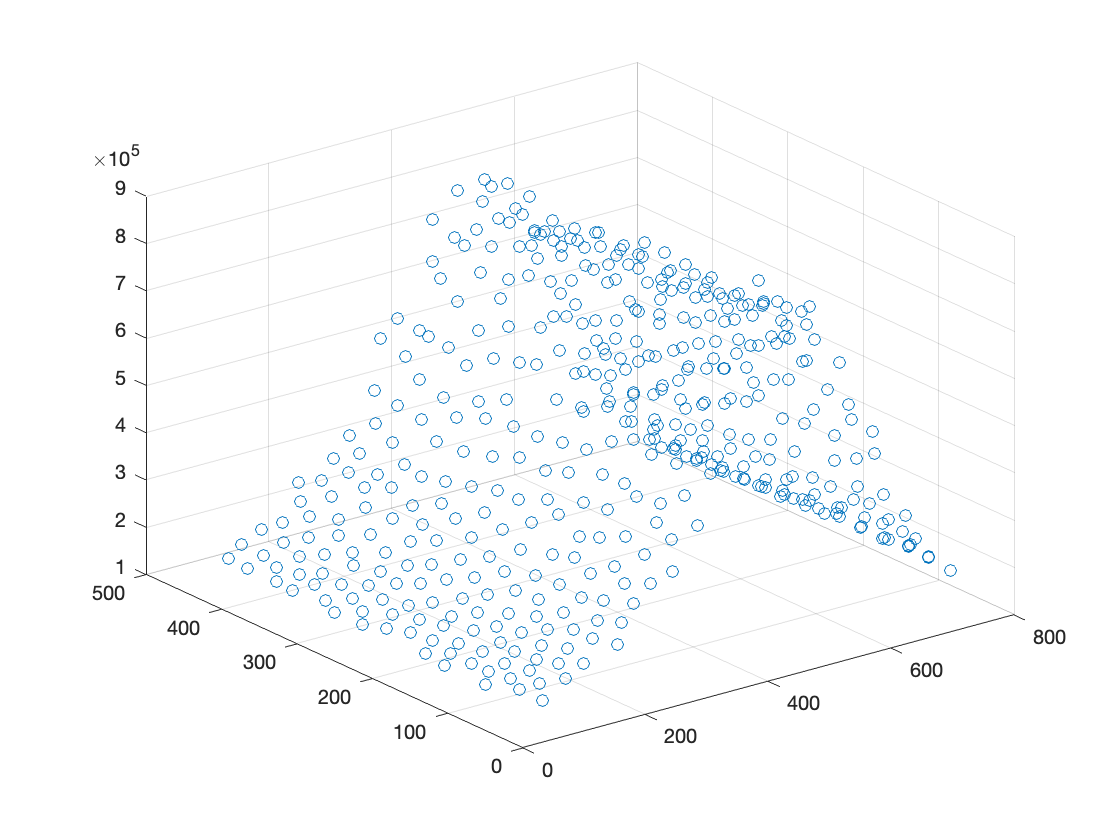

fig = figure;
scatter3(x_coord,y_coord,fluo)
savefig(fig,[FigPath,'/protein_scatter.fig'])

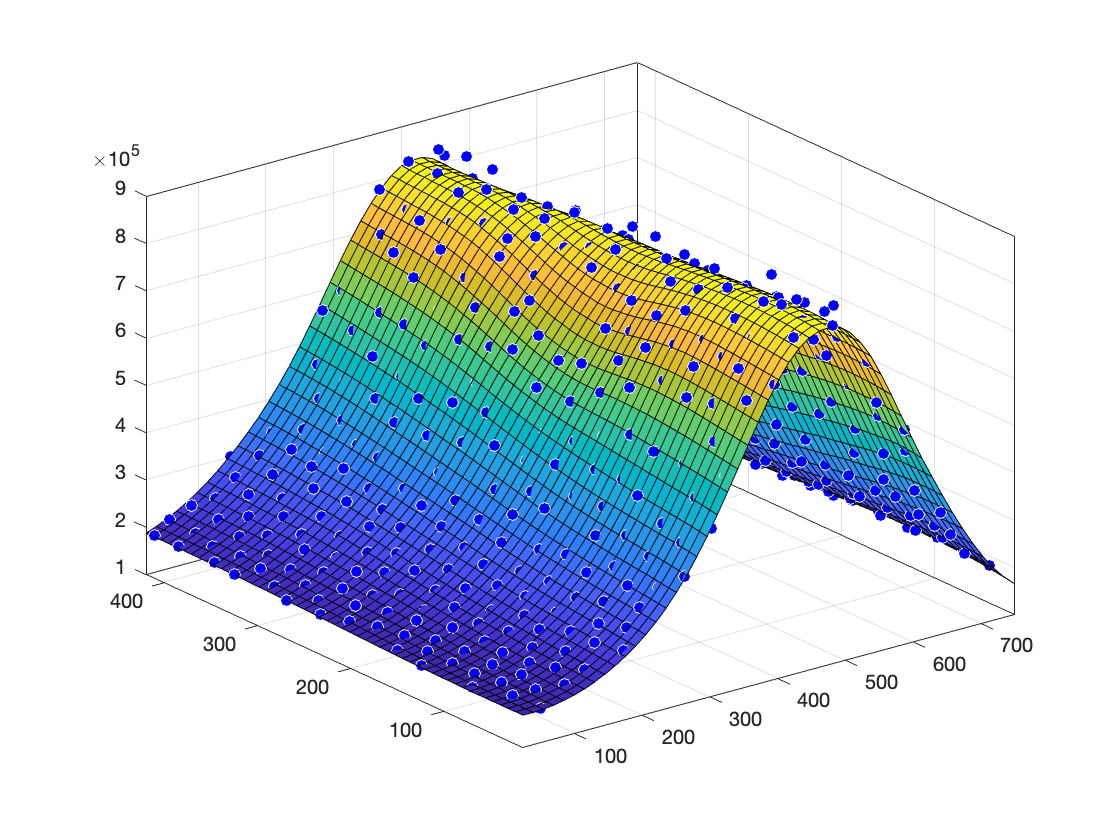


%sf1 = fit([x_coord,y_coord],fluo,'poly44');
%sf1 = fit([x_coord,y_coord],fluo,'linearinterp');
%sf1 = fit([x_coord,y_coord],fluo,'cubicinterp');
%sf1 = fit([x_coord,y_coord],fluo,'lowess');    % do not work

%sf1 = fit([x_coord,y_coord],fluo,'thinplateinterp');
%sf1 = fit([x_coord,y_coord],fluo,'biharmonicinterp');
%thinplateinterp

sf1 = fit([x_coord,y_coord],fluo,'loess'); % good, local quadratic regression

fig = figure;
plot(sf1,[x_coord,y_coord],fluo);
savefig(fig,[FigPath,'/protein_scatter_fit.fig'])

## Draw contour lines

% xlim = linspace(0,768,100);
% ylim = linspace(0,450,100);
% 
% f  = @(x,y)sf1(x,y);
% 
% 
% level = linspace(0,7E5,15);
% %fcontour(f,'LevelStepMode','manual','LevelStep',1E5)
% fcontour(f,[0 768 0 450],'LevelStep',0.25E5)
% 
% [X Y] = meshgrid(xlim,ylim);
% F = f(X,Y);
% 
% [U,V] = gradient(F);
% 
% hold on
% quiver(X,Y,U,V)
% hold off
% axis equal

## Part 5: Calibrate AP position

### Correction for the curvature

#### Try fitting the center line to quadratic function

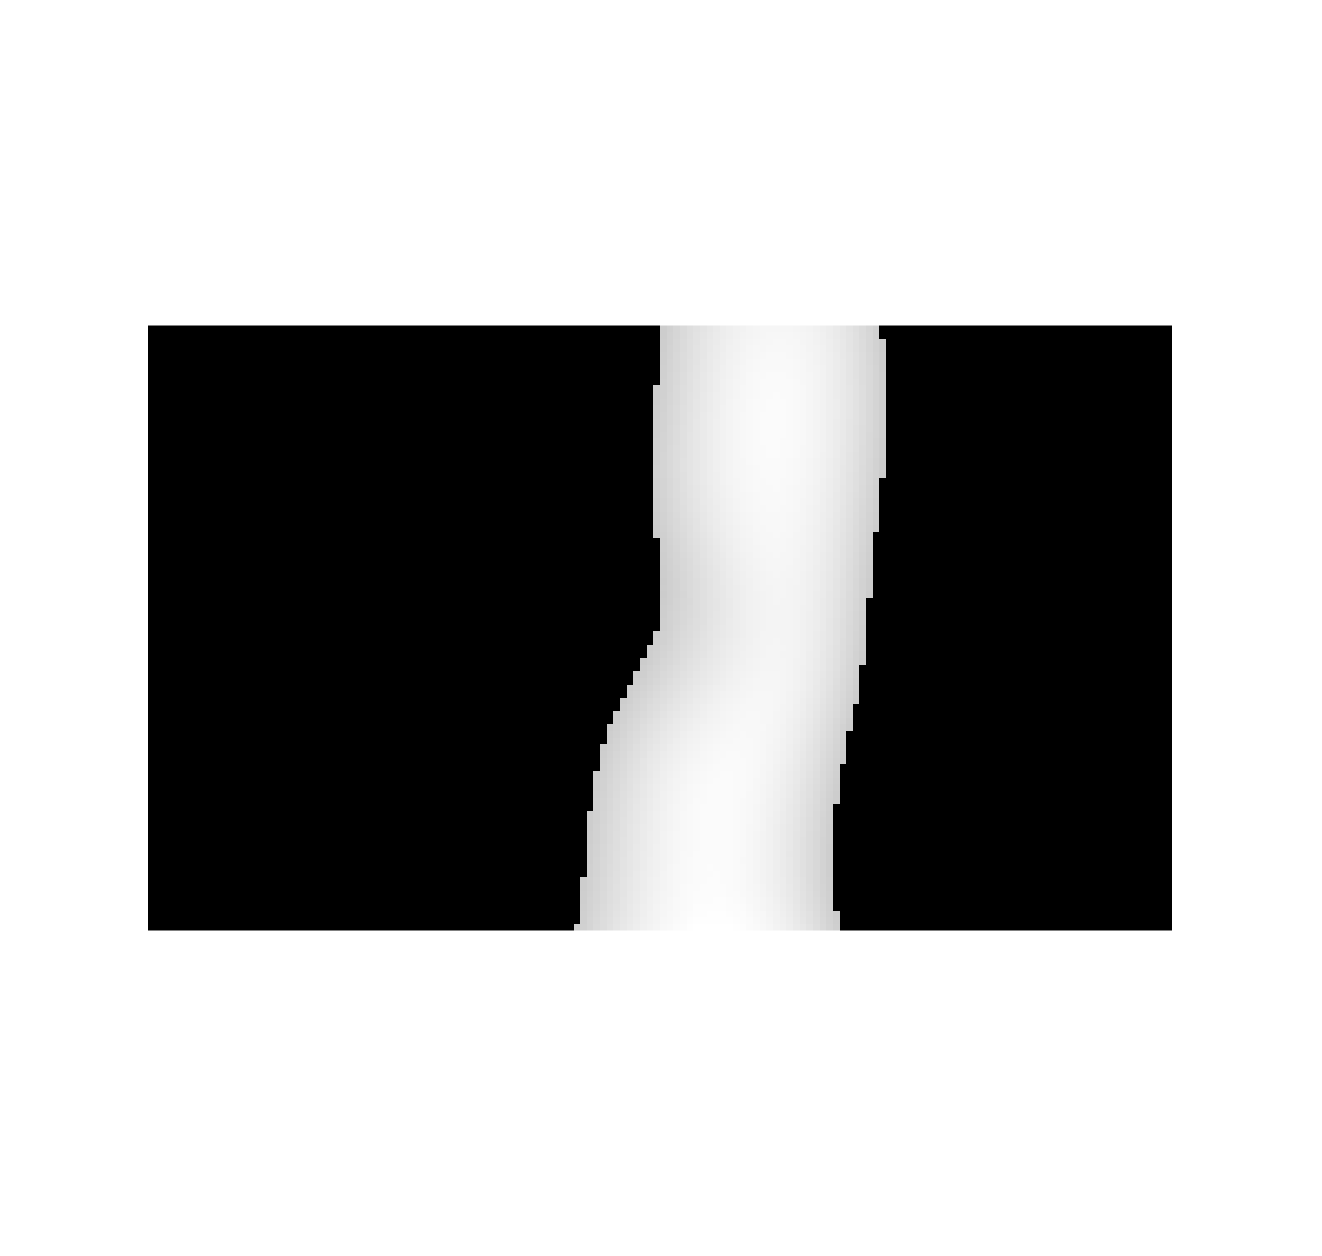

% Calculate coarse grained image
xscale = 5;
yscale = 5;

xlimit = 0:xscale:768;
ylimit = 0:yscale:450;

f  = @(x,y)sf1(x,y)-1E5;

[X Y] = meshgrid(xlimit,ylimit);
F = f(X,Y);

maxPeak = max(max(F));
% Extract stripe region
ImMask = F>maxPeak*0.8;
ImFluo = F.*ImMask;

fig = figure;
imshow(ImFluo,[])
truesize(fig,[512 512])

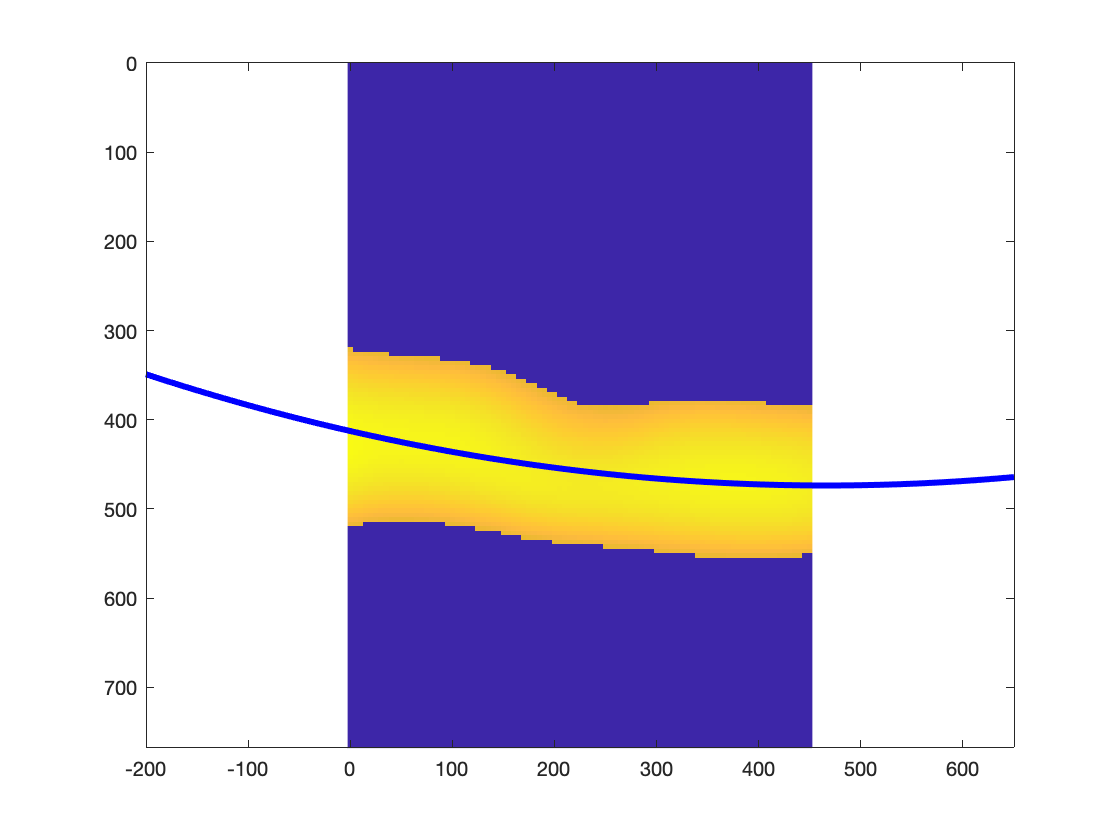

ImFluo_rot = imrotate(ImFluo,-90);
factor = length(xlimit);
k_temp = find(ImFluo_rot);
x_temp = floor(k_temp/factor)*xscale+1;
y_temp = mod(k_temp,factor)*yscale;
w = ImFluo_rot(k_temp);

%define model
modelFun2 = @(b,x) b(1)*x.^2+b(2)*x+b(3);
%modelFun3 = @(b,x) b(1)*x.^3+b(2)*x.^2+b(3)*x+b(4);

%initial condition
start2 = [0 0 0];
%start3 = [0 0 0 0];

%fit without weight
% %nlm3 = fitnlm(X(:),Y(:),modelFun2,start2);
%fit with weight
%wnlm3 = fitnlm(x_temp,y_temp,modelFun3,start3,'Weight',w);
wnlm2 = fitnlm(x_temp,y_temp,modelFun2,start2,'Weight',w);

fig = figure;
x_temp = [0 450];
y_temp = [0 768];
imagesc(x_temp,y_temp,ImFluo_rot);
xx = linspace(-200,650)';

%plot stripe 3
%line(xx,-predict(nlm3,xx),'linestyle','--','color','k','LineWidth',1.5);
line(xx,predict(wnlm2,xx),'color','b','LineWidth',3)
xlim([-200 650])
ylim([0 768])

### Calculate distance to the central curve

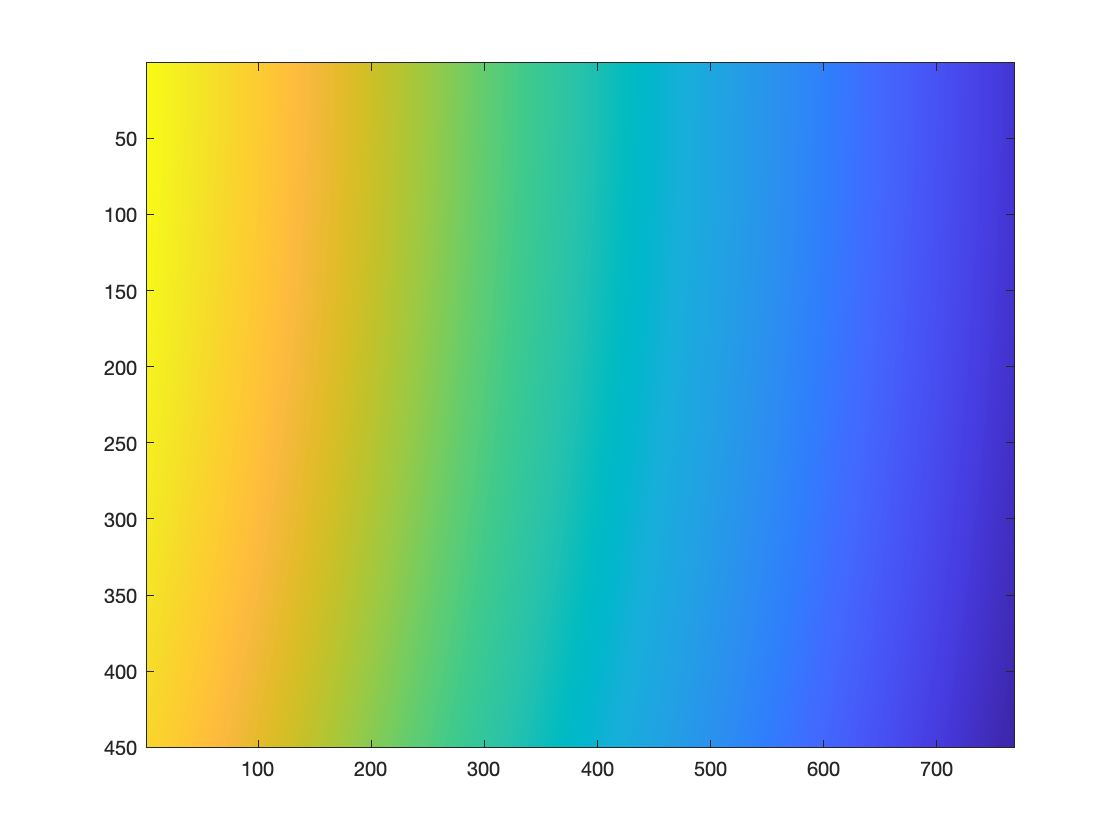

% initialize a meshgrid and central curve
xscale = 1;
yscale = 1;

xlimit = 1:xscale:768;
ylimit = 1:yscale:450;
[X Y] = meshgrid(xlimit,ylimit);

point_all = [X(:) Y(:)];
curve_all = [predict(wnlm2,xx) xx];

% calculate distance of each point to the central curve
[xy,distance,t] = distance2curve(curve_all,point_all);
point_predict = predict(wnlm2,point_all(:,2));
flag = point_predict>point_all(:,1);
distance(flag) = -distance(flag);

APmap = flip(reshape(distance,450,768),1);

if APflip
    APmap = -APmap;
end

fig = figure;
imagesc(APmap)

### Correction for embryo length

LoadAPDetPath = [DynamicsResultsFolder '/' Prefix '/APDetection.mat'];
APDetData = load(LoadAPDetPath);

APLength = sqrt(sum((APDetData.coordAZoom-APDetData.coordPZoom).^2));

APmap = APmap/APLength;

### Assign corrected AP positions

for i = 1:nucleiNum
    CompiledNucleiData(i).APPos = APmap(round(CompiledNucleiData(i).ycoordMean),round(CompiledNucleiData(i).xcoordMean));
end

## Part 7: Calculate parameters based on AP binning

### Bin nuclei based on AP position

% compile AP position
APPosTemp = [CompiledNucleiData(:).APPos];

% bin the nuclei based on average 
label = discretize(APPosTemp,edges);

### Calculate knirps and transcriptional signal

#### Initialize variables

nucleiNum = length(processed_data(initFrame).schnitznum);

nucleiBinNum = zeros(totalFrame,binNum-1); % number of nuclei in each bin
nuclearFluoAP = zeros(totalFrame,binNum-1);
nuclearFluoAPStd = zeros(totalFrame,binNum-1);
nuclearFluoAPErr = zeros(totalFrame,binNum-1);
spotFluoAP = zeros(totalFrame,binNum-1);
spotFluoAPStd = zeros(totalFrame,binNum-1);
spotFluoAPErr = zeros(totalFrame,binNum-1);

#### Calculate average protein and spot fluorescence for all frames

for i = initFrame:finalFrame
    
    % compile nuclei and spot fluorescence for the frame
    nucleiFluoTemp = zeros(nucleiNum,1);
    spotFluoTemp = zeros(nucleiNum,1);
    
    for j = 1:nucleiNum
        nucleiFluoTemp(j) = CompiledNucleiData(j).nuclearFluo(i-initFrame+1);
        spotFluoTemp(j) = CompiledNucleiData(j).spotFluo(i-initFrame+1);
    end
    
    for j = 1:binNum-1
        nucleiBinNum(i-initFrame+1,j) = length(find(label==j));
        nuclearFluoAP(i-initFrame+1,j) = mean(nucleiFluoTemp(label==j));
        nuclearFluoAPStd(i-initFrame+1,j) = std(nucleiFluoTemp(label==j));
        nuclearFluoAPErr(i-initFrame+1,j) = nuclearFluoAPStd(i-initFrame+1,j)/sqrt(nucleiBinNum(i-initFrame+1,j));
        
        spotFluoAP(i-initFrame+1,j) = mean(spotFluoTemp(label==j));
        spotFluoAPStd(i-initFrame+1,j) = std(spotFluoTemp(label==j));
        spotFluoAPErr(i-initFrame+1,j) = spotFluoAPStd(i-initFrame+1,j)/sqrt(nucleiBinNum(i-initFrame+1,j));
    end
    
end

#### Calculate moving average  (removed)

nuclearFluoAPMean = movmean(nuclearFluoAP,5,1);
spotFluoAPMean = movmean(spotFluoAP,5,1);
%nuclearFluoAPMean = nuclearFluoAP;
%spotFluoAPMean = spotFluoAP;

#### Plot figures

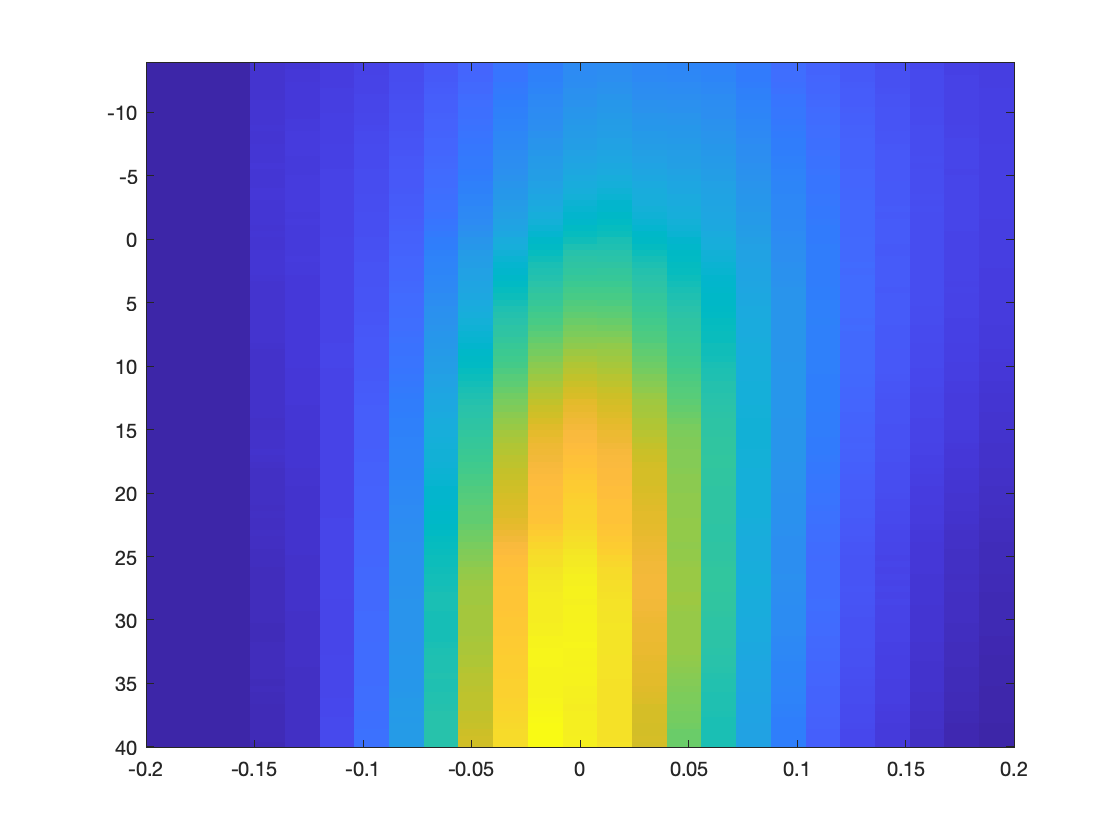

binAP = (edges(1:end-1)+edges(2:end))/2;

fig = figure;
imagesc(binAP,ElapsedTime,nuclearFluoAPMean)

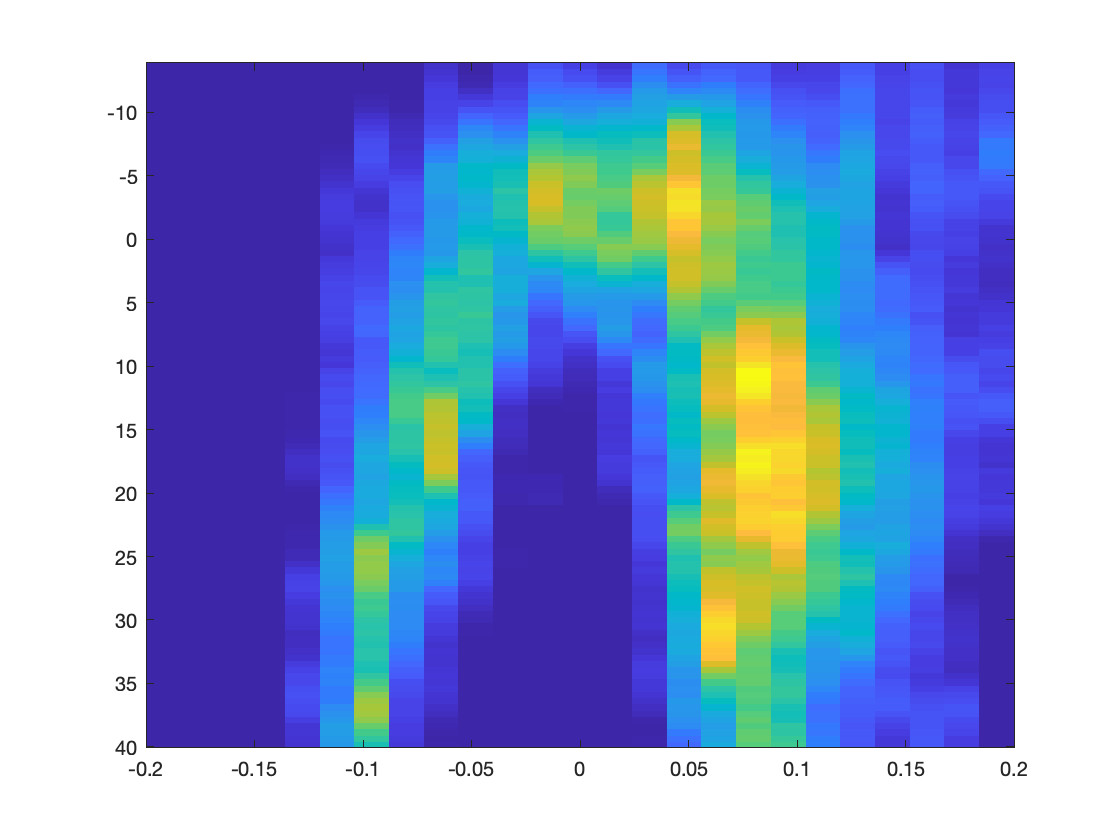

fig = figure;
imagesc(binAP,ElapsedTime,spotFluoAPMean)

### Calculate time on and mean transcription rate for each nuclei 

(similar to Lammers et al., 2020)

for i = 1:nucleiNum
    
    nuclearFluoTemp = CompiledNucleiData(i).nuclearFluo;
    spotFluoTemp = CompiledNucleiData(i).spotFluo;
    
    flag = find(spotFluoTemp>0);
    frame_end = find(totalTime(flag)<35);
    
    if isempty(flag)
        CompiledNucleiData(i).timeOnAll = 0;
        CompiledNucleiData(i).meanRateAll = nan; 
        CompiledNucleiData(i).timeOn = 0;
        CompiledNucleiData(i).meanRate = nan;
    else
        CompiledNucleiData(i).timeOn = length(flag)*1/3; % Need to change!!!
        CompiledNucleiData(i).meanRate = mean(spotFluoTemp(flag));
        
        if totalTime(max(flag))<35
            CompiledNucleiData(i).timeOnAll = totalTime(max(flag))-totalTime(min(flag));
            CompiledNucleiData(i).meanRateAll = mean(spotFluoTemp(min(flag):max(flag)));
        else
            CompiledNucleiData(i).timeOnAll = 35-totalTime(min(flag));
            CompiledNucleiData(i).meanRateAll = mean(spotFluoTemp(min(flag):max(frame_end)));
        end
    end
    
end

### Compile time on and mean transcription rate based on AP bins

% compile time on and mean rate for all nuclei
timeOnTemp = [CompiledNucleiData(:).timeOn];
meanRateTemp = [CompiledNucleiData(:).meanRate];

timeOnAllTemp = [CompiledNucleiData(:).timeOnAll];
meanRateAllTemp = [CompiledNucleiData(:).meanRateAll];

% initialize arrays
nucleiNumAP = zeros(binNum-1,1);
nucleiOnNumAP = zeros(binNum-1,1);

timeOnAllAP = zeros(binNum-1,1);
timeOnAllAPStd = zeros(binNum-1,1);
timeOnAllAPErr = zeros(binNum-1,1);
timeOnAP = zeros(binNum-1,1);
timeOnAPStd = zeros(binNum-1,1);
timeOnAPErr = zeros(binNum-1,1);

meanRateAllAP = zeros(binNum-1,1);
meanRateAllAPStd = zeros(binNum-1,1);
meanRateAllAPErr = zeros(binNum-1,1);
meanRateAP = zeros(binNum-1,1);
meanRateAPStd = zeros(binNum-1,1);
meanRateAPErr = zeros(binNum-1,1);

for i = 1:binNum-1
    
    nucleiNumAP(i) = length(find(label==i));
    nucleiOnNumAP(i) = length(find(~isnan(meanRateAllTemp(label==i)))); % exclude nuclei with nan
    
    meanRateAllAP(i) = mean(meanRateAllTemp(label==i),'omitnan');
    meanRateAllAPStd(i) = std(meanRateAllTemp(label==i),'omitnan');
    meanRateAllAPErr(i) = meanRateAllAP(i)/sqrt(nucleiOnNumAP(i));
    
    meanRateAP(i) = mean(meanRateTemp(label==i),'omitnan');
    meanRateAPStd(i) = std(meanRateTemp(label==i),'omitnan');
    meanRateAPErr(i) = meanRateAP(i)/sqrt(nucleiOnNumAP(i));
    
    timeOnAllAP(i) = mean(timeOnAllTemp(label==i));
    timeOnAllAPStd(i) = std(timeOnAllTemp(label==i));
    timeOnAllAPErr(i) = timeOnAllAP(i)/sqrt(nucleiNumAP(i));
    
    timeOnAP(i) = mean(timeOnTemp(label==i));
    timeOnAPStd(i) = std(timeOnTemp(label==i));
    timeOnAPErr(i) = timeOnAP(i)/sqrt(nucleiNumAP(i));

end


### Plot results

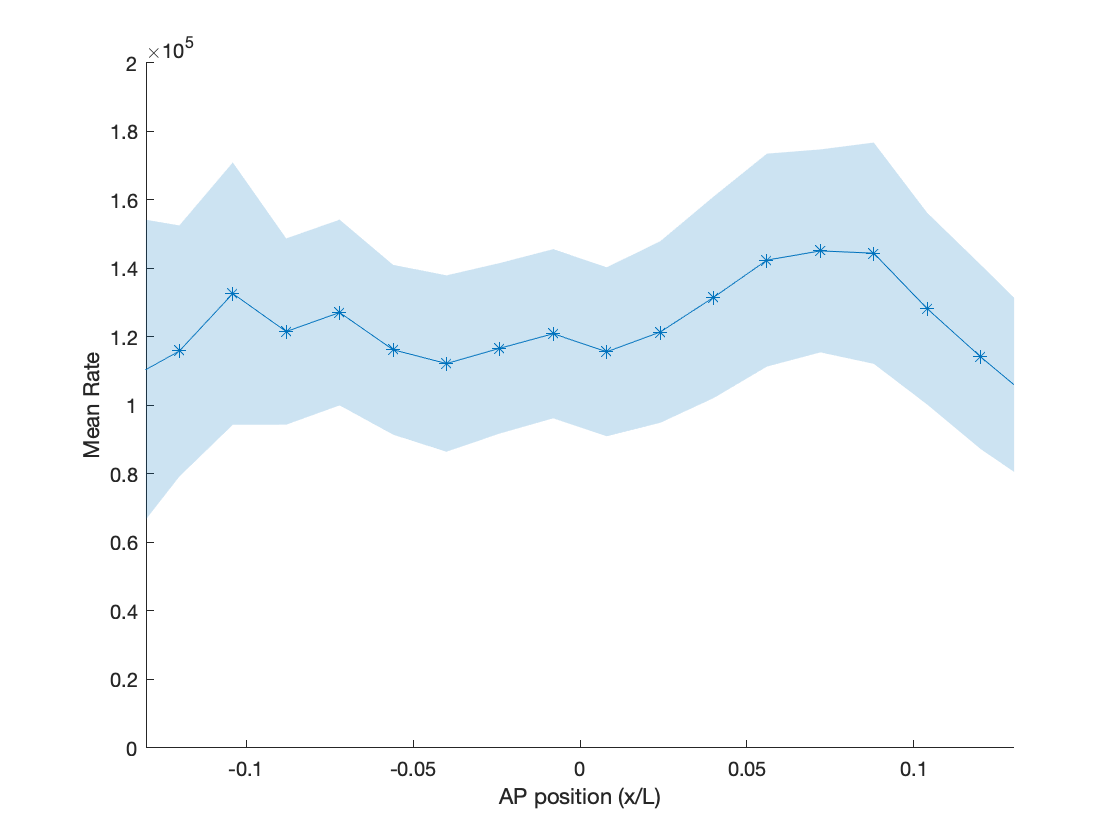

% meanRateAllFig = figure;
% boundedline(edges(1:end-1)', meanRateAllAP, meanRateAllAPErr, '-*','nan', 'gap','alpha');
% 
% xlabel('AP position (x/L)')
% ylabel('Mean Rate')
% 
% xlim([-0.13 0.13])
% ylim([0 1.8E5])
% timeOnAllFig = figure;
% boundedline(edges(1:end-1)', timeOnAllAP, timeOnAllAPErr, '-*','nan', 'gap','alpha');
% 
% xlabel('AP position (x/L)')
% ylabel('Time On')
% 
% xlim([-0.13 0.13])
% ylim([0 40])

meanRateFig = figure;
boundedline(edges(1:end-1)', meanRateAP, meanRateAPErr, '-*','nan', 'gap','alpha');

xlabel('AP position (x/L)')
ylabel('Mean Rate')

xlim([-0.13 0.13])
ylim([0 2E5])

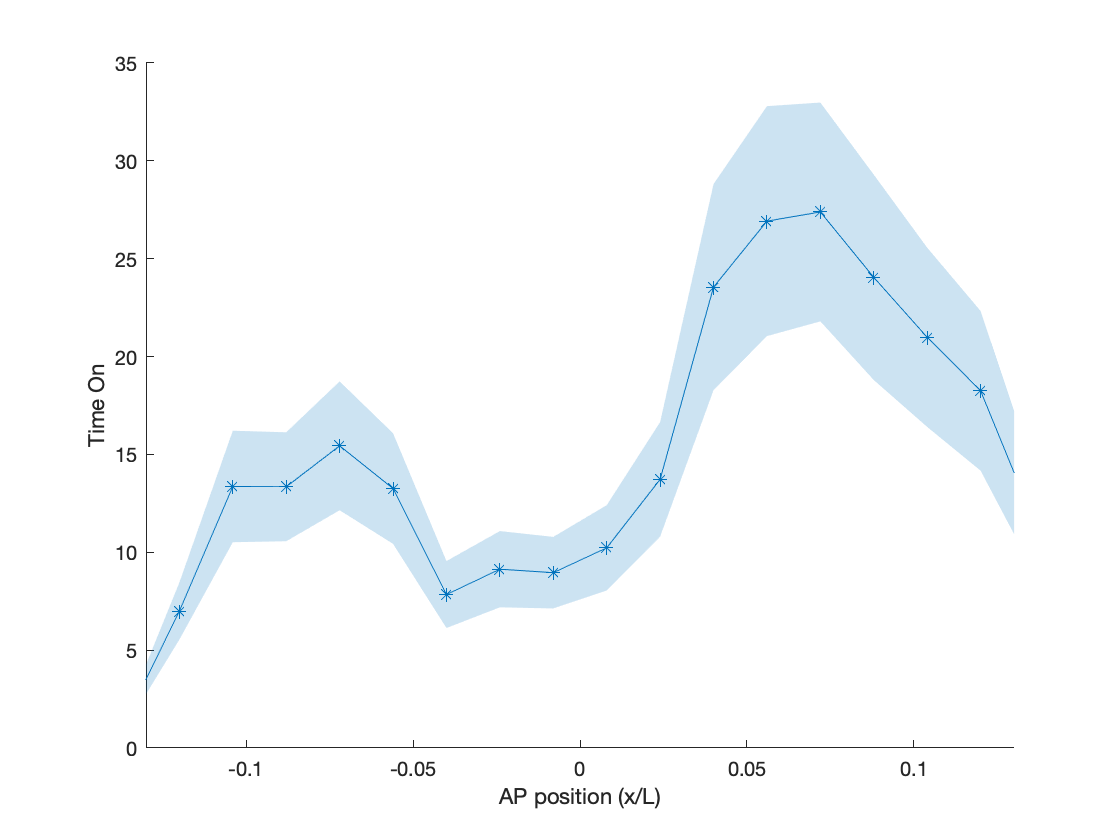

timeOnFig = figure;
boundedline(edges(1:end-1)', timeOnAP, timeOnAPErr, '-*','nan', 'gap','alpha');

xlabel('AP position (x/L)')
ylabel('Time On')

xlim([-0.13 0.13])
ylim([0 35])

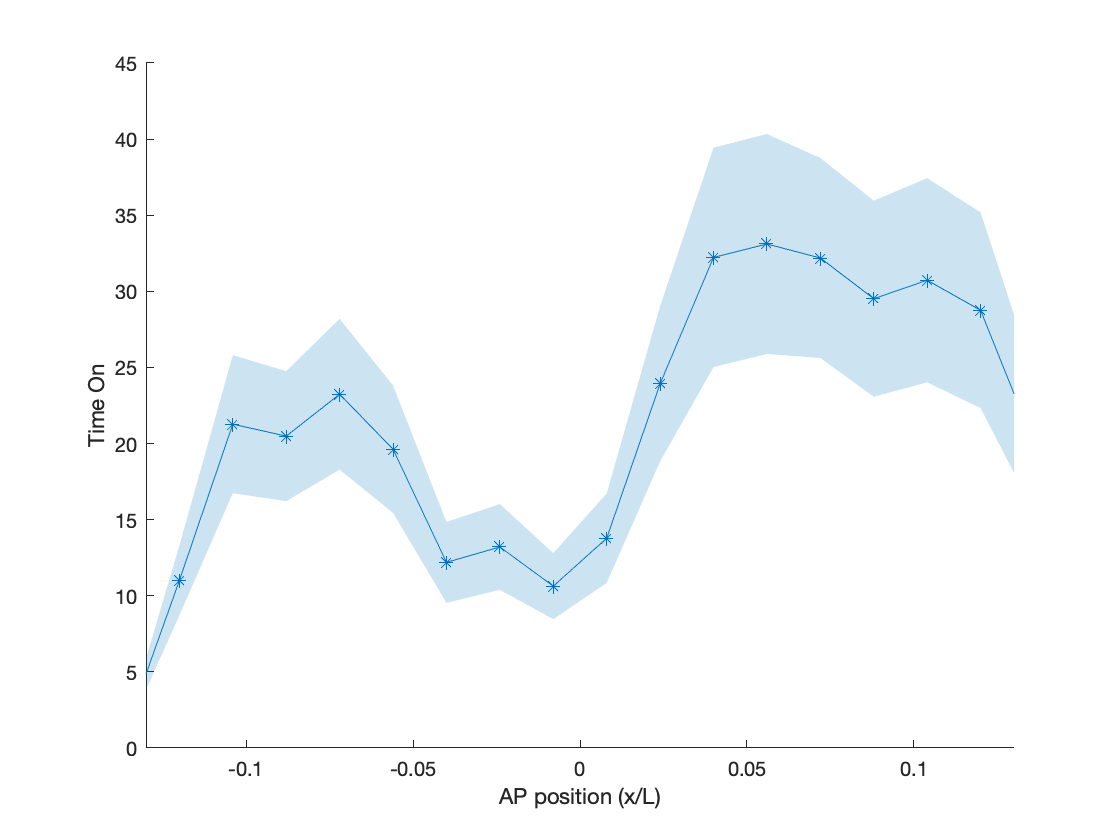

timeOnAllFig = figure;
boundedline(edges(1:end-1)', timeOnAllAP, timeOnAllAPErr, '-*','nan', 'gap','alpha');

xlabel('AP position (x/L)')
ylabel('Time On')

xlim([-0.13 0.13])
ylim([0 45])

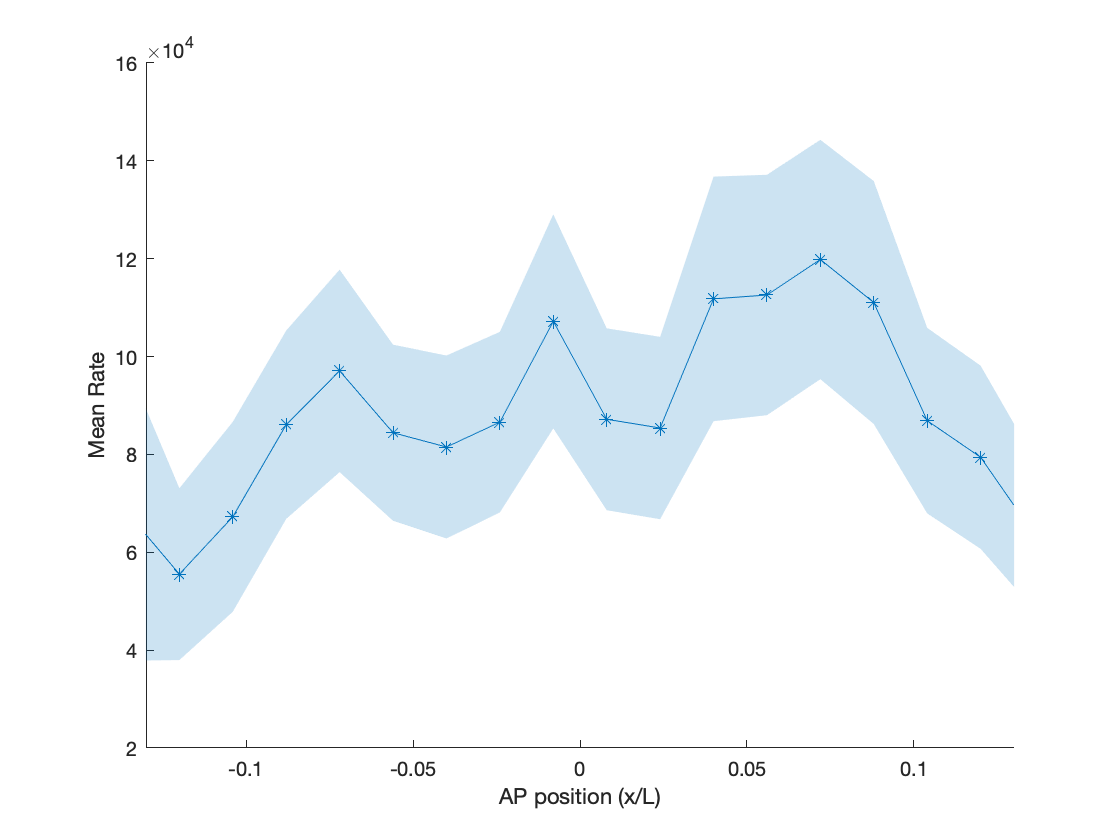

meanRateAllFig = figure;
boundedline(edges(1:end-1)', meanRateAllAP, meanRateAllAPErr, '-*','nan', 'gap','alpha');

xlabel('AP position (x/L)')
ylabel('Mean Rate')

xlim([-0.13 0.13])

%ylim([0 45])

### Interpolate results

nuclearFluoAPFinal = zeros(length(timeFinal),binNum-1);
spotFluoAPFinal = zeros(length(timeFinal),binNum-1);

for i = 1:binNum-1
    nuclearFluoAPFinal(:,i) = interp1(totalTime,nuclearFluoAPMean(:,i),timeFinal);
    spotFluoAPFinal(:,i) = interp1(totalTime,spotFluoAPMean(:,i),timeFinal);
end

## Save analysis result

save([ResultPath '/CompiledData.mat'],'timeFinal', 'binNum','edges','timeOnAllAP', 'timeOnAllAPErr', 'timeOnAllAPStd', ...
    'timeOnAP', 'timeOnAPErr', 'timeOnAPStd', 'meanRateAllAP', 'meanRateAllAPErr','meanRateAllAPStd', 'meanRateAP', 'meanRateAPErr','meanRateAPStd', ...
    'nuclearFluoAP','nuclearFluoAPErr','nuclearFluoAPFinal','nuclearFluoAPMean','nuclearFluoAPStd', ...
    'nucleiNum','nucleiNumAP','nucleiOnNumAP','spotFluoAP','spotFluoAPErr','spotFluoAPFinal','spotFluoAPMean','spotFluoAPStd');

## OLD!!!

## Part 6: Calculate average protein and spot fluorescence (binned by AP)

#### Initialize variables


% %frame_plot = 1:30:frame_num;
% frame_list = [6,31,71];
% 
% for i = 1:length(frame_list)
% 
%     frame_plot = frame_list(i);
%         
%     AvrProteinFig = figure;
%     
%     protein_err_plot = zeros(binNum-1,2,length(frame_plot));
%     spot_err_plot = zeros(binNum-1,2,length(frame_plot));
%     protein_err_plot(:,1,:) = nuclearFluoAPErr(frame_plot,:)';
%     protein_err_plot(:,2,:) = nuclearFluoAPErr(frame_plot,:)';
%     spot_err_plot(:,1,:) = spotFluoAPErr(frame_plot,:)';
%     spot_err_plot(:,2,:) = spotFluoAPErr(frame_plot,:)';
%     
%     yyaxis left
%     boundedline(edges(1:end-1)', nuclearFluoAP(frame_plot,:)',protein_err_plot, '-*','nan', 'gap','alpha');
%     ylabel('Protein (AU)')
%     ylim([0 1E6])
%     
%     yyaxis right
%     boundedline(edges(1:end-1)', spotFluoAP(frame_plot,:)',spot_err_plot, '-*','nan', 'gap','alpha');
%     ylim([0 2.5E5])
%     
%     xlabel('AP position (x/L)')
%     xlim([-0.13 0.13])
% end

### Plot trajectories at different bins

% bin_plot = 16;
% 
% AvrBinProteinFig = figure;
% 
% protein_err_plot = zeros(totalFrame,2,length(bin_plot));
% spot_err_plot = zeros(totalFrame,2,length(bin_plot));
% protein_err_plot(:,1,:) = nuclearFluoAPErr(:,bin_plot)';
% protein_err_plot(:,2,:) = nuclearFluoAPErr(:,bin_plot)';
% spot_err_plot(:,1,:) = spotFluoAPErr(:,bin_plot)';
% spot_err_plot(:,2,:) = spotFluoAPErr(:,bin_plot)';
% 
% yyaxis left
% boundedline(totalTime, nuclearFluoAP(:,bin_plot),protein_err_plot, '-*','nan', 'gap','alpha');
% ylabel('Protein (AU)')
% ylim([0 8E5])
% 
% yyaxis right
% boundedline(totalTime, spotFluoAP(:,bin_plot)',spot_err_plot, '-*','nan', 'gap','alpha');
% ylim([0 3E5])
% 
% xlabel('Time (min)')

## Part 6 v2: Calculate average protein and spot (binned by knirps concentration)

### Assign each nuclei to bins based on nuclear concentration

% % initialization
% binNum_fluo = 32;
% edges_fluo = linspace(0,6.3E5,binNum);
% 
% totalFrame = finalFrame-initFrame+1; % number of nuclei in the frame
% nucleiNum = length(processed_data(initFrame).schnitznum);
% 
% nuclei_bin_num_fluo = zeros(totalFrame,binNum_fluo-1); % number of nuclei in each bin
% protein_avr_fluo = zeros(totalFrame,binNum_fluo-1);
% protein_std_fluo = zeros(totalFrame,binNum_fluo-1);
% protein_err_fluo = zeros(totalFrame,binNum-1);
% spot_avr_fluo = zeros(totalFrame,binNum_fluo-1);
% spot_std_fluo = zeros(totalFrame,binNum_fluo-1);
% spot_err_fluo = zeros(totalFrame,binNum_fluo-1);
% 
% % calculate fitted fluorescence for each position
% fluo_fit = f(x_coord,y_coord);
% 
% % assign bins to each the nuclei
% label = discretize(fluo_fit,edges_fluo);
% 
% % calculate average protein and spot fluorescence for all frames
% for i = initFrame:finalFrame
% 
%     xcoord = processed_data(i).xcoord;
%     ycoord = processed_data(i).ycoord;
%     protein_fluo = processed_data(i).NuclearFluo;
%     spot_fluo = processed_data(i).SpotFluo;
%     
%     for j = 1:binNum_fluo-1
%         nuclei_bin_num_fluo(i-initFrame+1,j) = length(find(label==j));
%         protein_avr_fluo(i-initFrame+1,j) = mean(protein_fluo(label==j))-eYFP_background;
%         protein_std_fluo(i-initFrame+1,j) = std(protein_fluo(label==j));
%         protein_err_fluo(i-initFrame+1,j) = nuclearFluoAPStd(i-initFrame+1,j)/sqrt(nucleiBinNum(i-initFrame+1,j));
%         
%         spot_avr_fluo(i-initFrame+1,j) = mean(spot_fluo(label==j));
%         spot_std_fluo(i-initFrame+1,j) = std(spot_fluo(label==j));
%         spot_err_fluo(i-initFrame+1,j) = spotFluoAPStd(i-initFrame+1,j)/sqrt(nucleiBinNum(i-initFrame+1,j));
%     end
%     
% end
% 
% 
% %frame_plot = 1:30:frame_num;
% frame_list = [6,31];
% 
% for i = 1:length(frame_list)
% 
%     frame_plot = frame_list(i);
%         
%     AvrProteinFig = figure;
%     
%     protein_err_fluo_plot = zeros(binNum_fluo-1,2,length(frame_plot));
%     spot_err_fluo_plot = zeros(binNum_fluo-1,2,length(frame_plot));
% %     protein_err_fluo_plot(:,1,:) = protein_err_fluo(frame_plot,:)';
% %     protein_err_fluo_plot(:,2,:) = protein_err_fluo(frame_plot,:)';
% %     spot_err_fluo_plot(:,1,:) = spot_err_fluo(frame_plot,:)';
% %     spot_err_fluo_plot(:,2,:) = spot_err_fluo(frame_plot,:)';
%     
%     protein_err_fluo_plot(:,1,:) = protein_std_fluo(frame_plot,:)';
%     protein_err_fluo_plot(:,2,:) = protein_std_fluo(frame_plot,:)';
%     spot_err_fluo_plot(:,1,:) = spot_std_fluo(frame_plot,:)';
%     spot_err_fluo_plot(:,2,:) = spot_std_fluo(frame_plot,:)';
%     
%     yyaxis left
%     boundedline(edges_fluo(1:end-1)', protein_avr_fluo(frame_plot,:)',protein_err_fluo_plot, '-*','nan', 'gap','alpha');
%     ylabel('Protein (AU)')
%     ylim([0 1E6])
%     
%     yyaxis right
%     boundedline(edges_fluo(1:end-1)', spot_avr_fluo(frame_plot,:)',spot_err_fluo_plot, '-*','nan', 'gap','alpha');
%     ylim([0 2.5E5])
%     
%     %xlabel('AP position (x/L)')
%     %xlim([-0.13 0.13])
% end

## Moving average

% protein_avr_fluo_mov = movmean(protein_avr_fluo,5,1);
% spot_avr_fluo_mov = movmean(spot_avr_fluo,5,1);
% 
% fig = figure;
% imagesc(spot_avr_fluo_mov)
% fig = figure;
% imagesc(protein_avr_fluo_mov)
% colorbar
% caxis([0 6.3E5])
% 
% bin_plot = 28;
% 
% fig = figure;
% yyaxis left
% plot(totalTime,protein_avr_fluo_mov(:,bin_plot))
% yyaxis right
% plot(totalTime,spot_avr_fluo_mov(:,bin_plot))

### Plot input-output function

% max_bin = max(label);
% 
% fig = figure;
% hold on
% 
% for i = initFrame+30:1:finalFrame-20
% %for i = start_frame:final_frame
% plot(protein_avr_fluo_mov(i-initFrame+1,:),spot_avr_fluo_mov(i-initFrame+1,:),'-o')
% end
% 
% xlim([0 8E5])

Part 6: Calculate mean transcription rate and transcription time window